load sampleEEGdata.mat

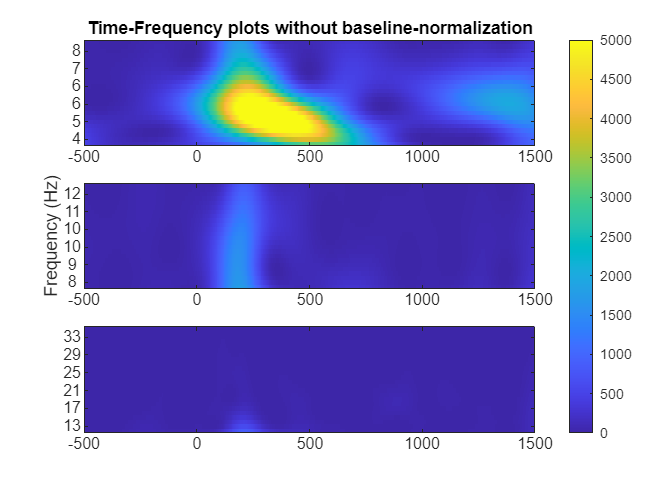

ndiv = 24;

freq_band1 = linspace(4,8,ndiv);
freq_band2 = linspace(8,12,ndiv);
freq_band3 = linspace(12,35,ndiv);

time = -1:1/EEG.srate:1;
hf_wv_size = (length(time) - 1)/2;

e = 37;
signal = squeeze(mean(EEG.data(:,:,:),3));

n_signal = length(signal);
n_wavelet= length(time);
n_conv = n_signal + n_wavelet - 1;
n_conv_pow2 = pow2(nextpow2(n_conv)); %Optimizing FFT

fft_s = fft(signal, n_conv_pow2,2);
tf_mat = zeros(ndiv,EEG.pnts,3,EEG.nbchan);

for fi = 1:length(freq_band1)
    s = 6/(2*pi*freq_band1(fi));
    m_wvlet = exp(2*pi*1i*freq_band1(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size);

    tf_mat(fi,:,1,:) = ifft_s';
end

for fi = 1:length(freq_band2)
    s = 6/(2*pi*freq_band2(fi));
    m_wvlet = exp(2*pi*1i*freq_band2(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size);

    tf_mat(fi,:,2,:) = ifft_s';
end

for fi = 1:length(freq_band3)
    s = 6/(2*pi*freq_band3(fi));
    m_wvlet = exp(2*pi*1i*freq_band3(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size);

    tf_mat(fi,:,3,:) = ifft_s';
end

tf_pow_mat = abs(tf_mat).^2;

figure;
ytickskip = 2:4:ndiv;
tiledlayout(3,1)

%TF plot for theta band without baseline normalization

nexttile()
imagesc(EEG.times, [], tf_pow_mat(:,:,1,e))
title("Time-Frequency plots without baseline-normalization")
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band1(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

%TF plot for alpha band without baseline normalization
nexttile()
imagesc(EEG.times, [], tf_pow_mat(:,:,2,e))
ylabel("Frequency (Hz)")
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band2(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

%TF plot for beta band without baseline normalization
nexttile()
imagesc(EEG.times, [], tf_pow_mat(:,:,3,e))
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band3(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

cb = colorbar();
cb.Layout.Tile = 'east';

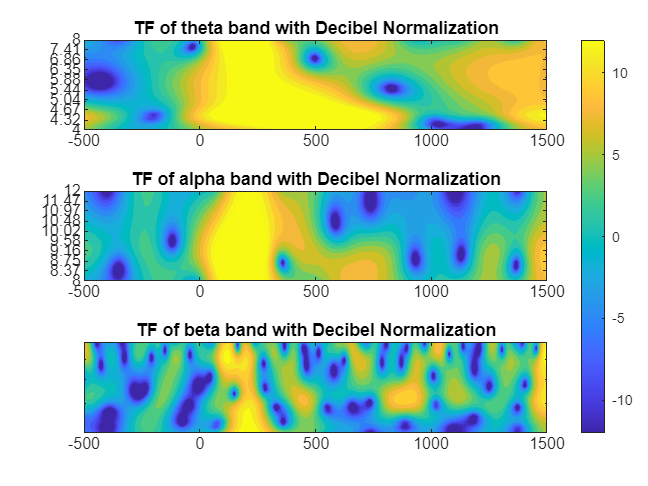

tf_dB = zeros(ndiv,EEG.pnts,3, EEG.nbchan);

baselinetime = [-400 -100]; % in ms

[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

baseline_power = mean(tf_pow_mat(:,baselineidx(1):baselineidx(2),:,:),2);

for band = 1:3
    tf_dB(:,:,band,:) = 10*log10(bsxfun(@rdivide, tf_pow_mat(:,:,band,:), baseline_power(:,:,band,:)));
end

figure;
ytickskip = 2:4:ndiv;
tiledlayout(3,1)

%TF plot for theta band with baseline normalization

nexttile()
contourf(EEG.times,freq_band1, tf_dB(:,:,1,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band1(1)),log10(freq_band1(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of theta band with Decibel Normalization')

%TF plot for alpha band with baseline normalization
nexttile()
contourf(EEG.times,freq_band2, tf_dB(:,:,2,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band2(1)),log10(freq_band2(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of alpha band with Decibel Normalization')

%TF plot for beta band with baseline normalization
nexttile()
contourf(EEG.times,freq_band1, tf_dB(:,:,3,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band3(1)),log10(freq_band3(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of beta band with Decibel Normalization')

cb = colorbar();
cb.Layout.Tile = 'east';